surf(delay*1e6,doppler/1e3,lfmaf,'LineStyle',...
    'none')
xlim([-tau_fm tau_fm]*1e6)
ylim([-bw bw]*1e-3)
colorbar
view([-40,35])
xlabel('Delay $\tau$ ($\mu$s)','interpreter',...
    'latex')
ylabel('Doppler $f_d$ (kHz)','interpreter',...
    'latex'); axe()
sgtitle(['Linear FM Pulse Waveform Ambiguity' ...
    ' Function'],'interpreter', 'latex')

imagesc(delay*1e6,doppler/1e3,mag2db(lfmaf))

imagesc(delay*1e6,doppler/1e3,mag2db(lfmaf))
xlim([-tau_fm tau_fm]*1e6)
ylim([-bw bw]*1e-3)
clim([-30 0])
cbar = colorbar;
cbar.Label.String = '(dB)';
axis xy
xlabel('Delay $\tau$ ($\mu$s)','interpreter',...
    'latex')
ylabel('Doppler $f_d$ (kHz)','interpreter',...
    'latex'); axe()

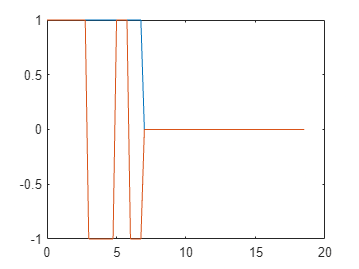

wav = step(barkerwav); up = 75;
barkersamples = barkerwav();
nsamp = size(wav(1:up),1);
t = (0:(nsamp-1))/fsB;
plot(t*1e6,[abs(wav(1:up)) barkersamples(1:up)])

title('Magnitude')